# Aproximação de uma função por lei de fourrier (n sei escrever)

## Boas práticas

clc;
clear all;
close all;

## Definição da funções que vão ser utilizadas

A função g é a que vai ser aproximada, e a função x é constante, e é utilizada na aproximação e cálculo do erro.

g  = @(t) exp(-t);              % função simples exponencial 
g2 = @(t) exp(10*-t);           % outra função pedida
g3 = @(t) exp(-(t-1));          % mais uma função
x = @(t,n,wo) exp(-j*n*wo*t);   % função constante utilizada na projeção
xn = @(t,n,wo) exp(j*n*wo*t);   % xn é a mesma função que x, porém com j positivo
% que é essencial para a soma realizada no final do programa


$$g=e^{-t}$$



$$x=e^{-\mathrm{jn}\omega \mathrm{ot}}$$



$$\mathrm{xn}=e^{\mathrm{jn}\omega \mathrm{ot}}$$


## Definição das variaveis

Variáveis tanto simbólicas como normais são utilizadas, e vão ser definidas aqui.

% wo --> frequência angular fundamnetal
wo = 2*pi;
% t  --> variável tempo
syms t;
% j  --> variável complexa
% nativo do matlab
% "N" é a quantidade de aproximações que vão ser realizadas
N = 10;
% n  --> variação da frequência do sinal
n  = [-N:1:N];
% n é de certa forma a quantidade de erros calculados

% T0 é utilizado no calculo das somas, ele representa o limite máximo de
% integração, e como nossa função só vai ser aproximada até t=1, logo T0
% vai ser = 1 também
T0 = 1;

## Calculo da projeção (Q2)

A função utilizada calcula a projeção entre as duas funções, o que caracteriza o erro da aproximação, será feita essa projeção tanto para o erro positivo (c1) quanto o negativo (c-1), o "for" utilizado tem o propósito de calcular essa projeção N vezes indicada, que depois será usado para a soma final das funções e assim a aproximação final.

% esse código também foi copiado do professor, desculpa mas sou burro dms
% pra fazer isso na mão
for k = 1:2*N+1 

clc;
% calculo dos coeficientes de todas as 3 funções
c(k) = projecao(g(t),x(t,n(k),wo),0,1);
c2(k) = projecao(g2(t),x(t,n(k),wo),0,1);
c3(k) = projecao(g3(t),x(t,n(k),wo),1,2);

% esse "projecao" é uma função customizada que o prof fez, vou utilizála
% também para ficar mais facil

end

O calculo realizado pela projeção é parecido com algo assim:


$$c_1 =\frac{\int_{\textrm{t0}} e^{-\textrm{jnwot}} \textrm{dt}}{\int_{\textrm{t0}} |e^{-\textrm{jnwot}} |^2 }$$
    
$$c_{-1} =\frac{\int_{\textrm{t0}} e^{\textrm{jnwot}} \textrm{dt}}{\int_{\textrm{t0}} |e^{-\textrm{jnwot}} |^2 }$$


## Soma dos "cs" e calculo do resíduo:

A soma dos "cs" é o que vai levar à função final utilizada na aproximação, o resíduo é utilizado como forma para decidir se a aproximação foi bem succedida, pois o resíduo caracteriza o erro total da operação.

Res   = 1e-3;               % resolução
% a resolução está ai por motivos computacionais, é utilizada pra criar um
% vetor tempo (utilizado a seguir) para os calculos da soma e afins
tempo = [0:Res:1];          % vetor tempo
tempo2 = [1:Res:2];
% expliquei acima (espero)
w0    = wo/T0;            % frequência
% esse w0 é diferente do wo utilizado no começo do problema, de certa
% forma é apenas o wo, porém dividido por T0, o que nesse caso os
% torna exatamente iguais, mas nem sempre vai ser assim
% p0    = c(N+1);             % Neste valor o n é zero
% o index onde n é zero se encontra em N+1
pesq = N+1;

for k=1:N

    p(:,k) = c(pesq-k)*x(tempo, n(pesq+k), w0) + c(pesq+k)*xn(tempo, n(pesq+k), w0);
    % faz a soma das projeções com as funções x e xn, que as converte em
    % uma base seno / cosseno
    r(:,k) = g(tempo)' - sum(p(:,k));
    % faz a soma e calcula o residuo
    totalp(:,k) = sum(p(:,k));
    % contem a soma que está dentro do p

end


$$\begin{array}{l}
e^{j\theta } =\cos \theta +\mathrm{jsen}\theta \\
e^{-j\theta } =\cos \theta -\mathrm{jsen}\theta 
\end{array}$$



$$\begin{array}{l}
e^{j\theta } +e^{-j\theta } =2\cos \theta \\
e^{j\theta } -e^{-j\theta } =2\mathrm{jsen}\theta 
\end{array}$$


## Cálculo das potências (Q1)

% Q1

pg1 = 1/T0*(int(g(t)*g(t),t,0,T0));
eval(pg1)

ans = 0.4323

pg2 = 1/T0*(int(g2(t)*g2(t),t,0,T0));
eval(pg2)

ans = 0.0500

pg3 = 1/T0*(int(g3(t)*g3(t),t,1,2));
eval(pg3)

ans = 0.4323

Como é possível perceber, a potência pg1 e pg3 são iguais, e isso se deve ao fato das funções terem a mesma forma

## Plot das funções em um gráfico (Q3)

Esta etapa tem uma função parecida com o calculo do resíduo, que é verificar se a aproximação foi bem sucedida.

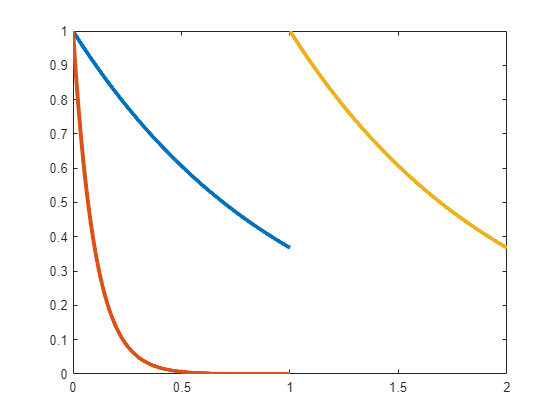

%Q3
% plot dos gráficos da função
plot(tempo,g(tempo)','LineWidth',3);
hold on;
plot(tempo,g2(tempo)','LineWidth',3);
plot(tempo2,g3(tempo2)','LineWidth',3);
hold off

% plot(tempo,sum(p')+c(pesq),'LineWidth',3)
% eu não sei pra que server o ', mas acho que significa o ultimo numero do
% array? Ou talvez até a soma de todos? Nem ideia.

## Plot dos cs (Q4)

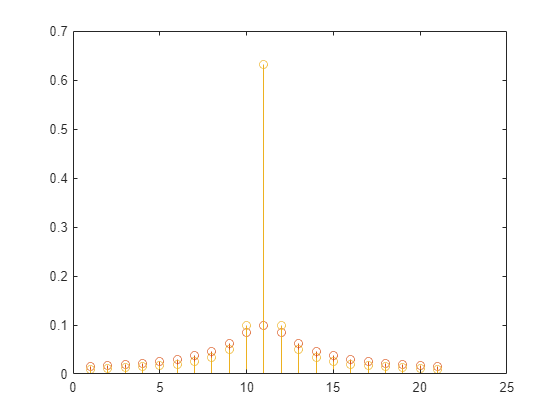

% stem dos coeficientes de todas as funções
stem(abs(c));
hold on
stem(abs(c2));
stem(abs(c3));
hold off

## Relacionando as questões 2 (cns), 3 (plot dos gráficos) e 4 (plot dos cns) com a questão 1 (potências)

Vendo os resultados da questão 1 (potências) é possivel perceber que as funções g e g3 tem a mesma potência, e isso se deve ao fato de que, em seus respectivos intervalos, as função tem a mesma forma e amplitude como mostrado na questão 3.

O resultado da qustão 4, e subsequentemente a questão 2, também representam esse fenômeno, pois os valores também são iguais.